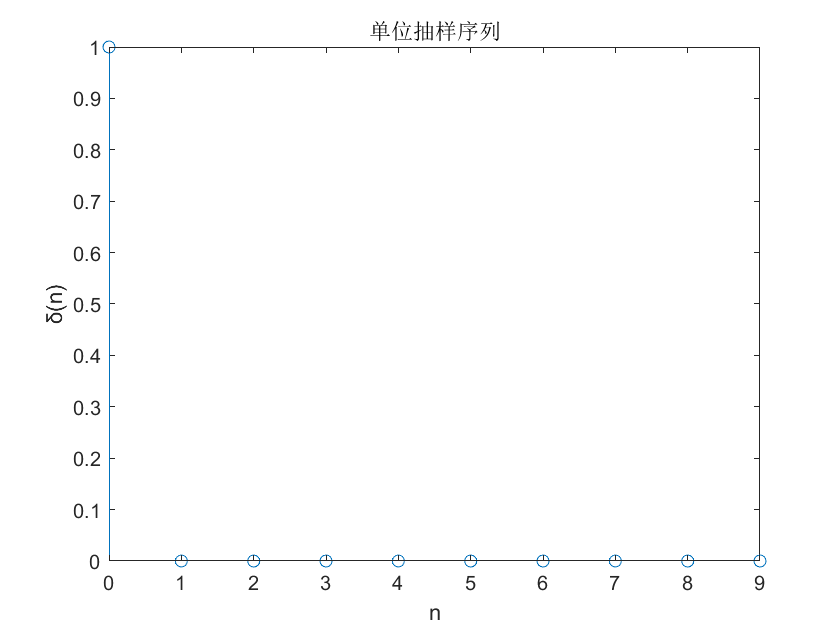

% 单位抽样序列
N = 10; % 信号长度
delta = zeros(1, N); % 初始化单位抽样序列
delta(1) = 1; % 设置n=0时为1
figure;
stem(0:N-1, delta);
title('单位抽样序列');
xlabel('n');
ylabel('δ(n)');

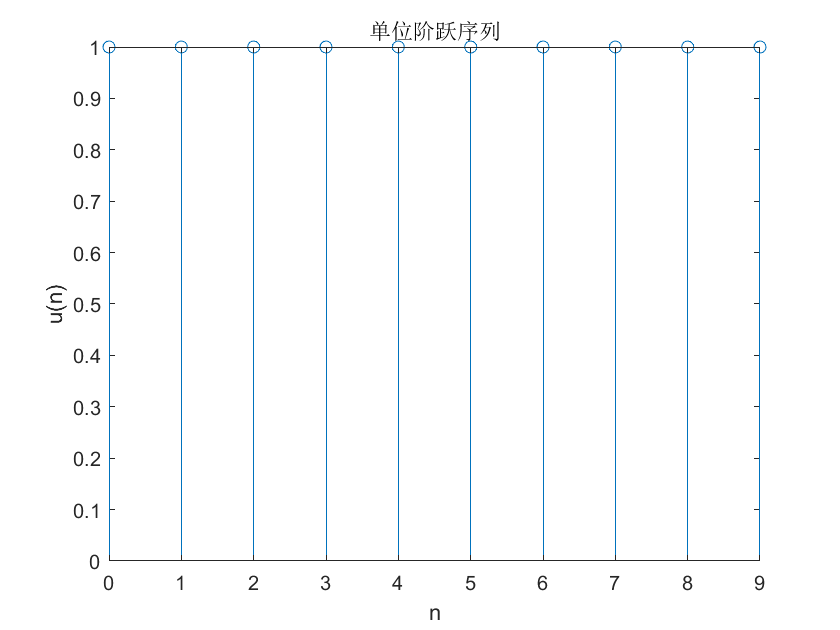


% 单位阶跃序列
u = ones(1, N); % 生成单位阶跃序列
figure;
stem(0:N-1, u);
title('单位阶跃序列');
xlabel('n');
ylabel('u(n)');

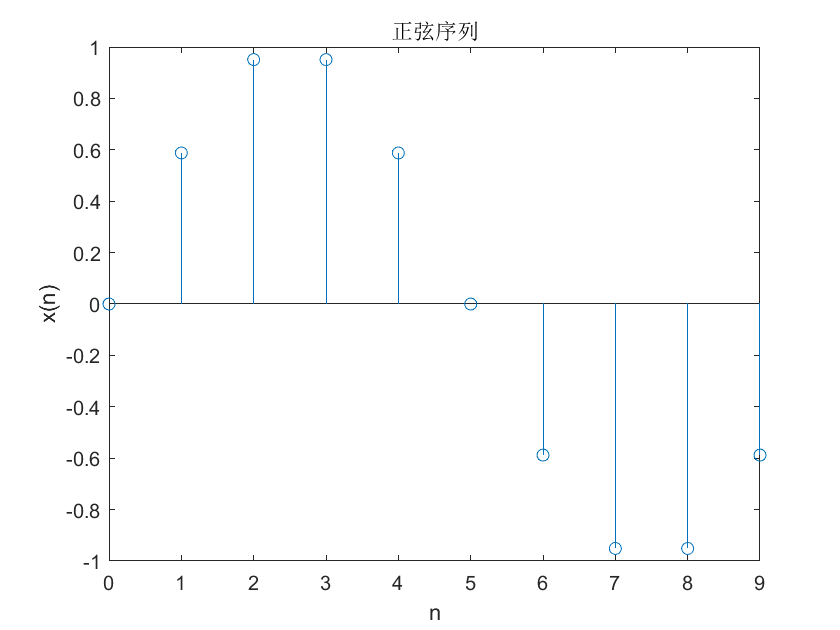


% 正弦序列
A = 1; % 振幅
f = 1; % 频率
Fs = 10; % 采样频率
phi = 0; % 相位
n = 0:N-1;
x_sin = A * sin(2 * pi * f * n / Fs + phi);
figure;
stem(n, x_sin);
title('正弦序列');
xlabel('n');
ylabel('x(n)');

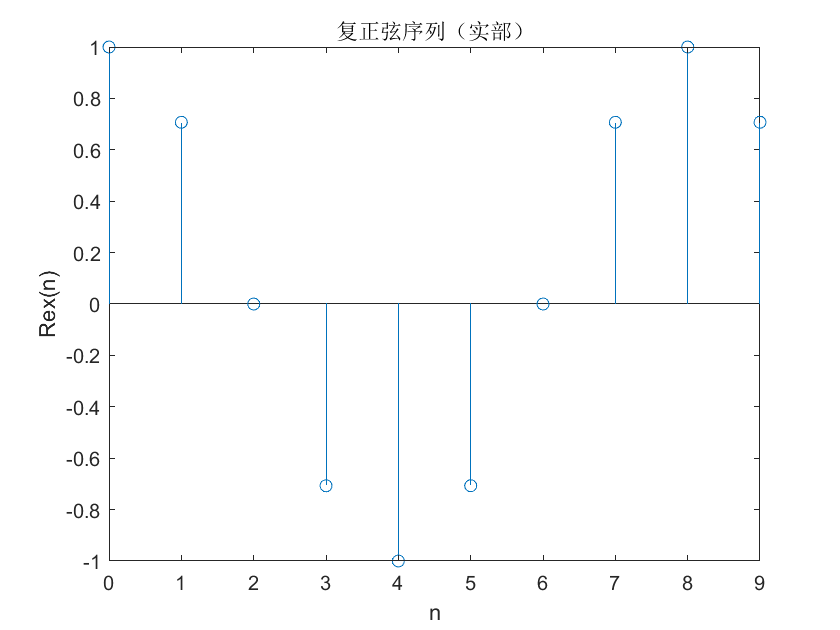


% 复正弦序列
w = pi/4; % 角频率
x_complex = exp(j * w * n);
figure;
stem(n, real(x_complex)); % 绘制实部
title('复正弦序列（实部）');
xlabel('n');
ylabel('Re{x(n)}');

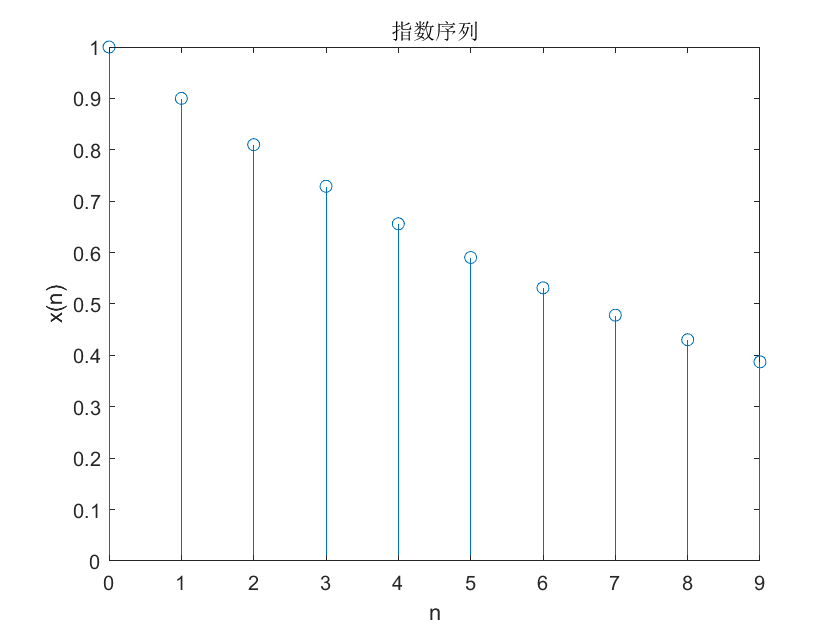


% 指数序列
a = 0.9; % 底数
x_exp = a.^n;
figure;
stem(n, x_exp);
title('指数序列');
xlabel('n');
ylabel('x(n)');